 
hold on
grid on
T = [30.1 40 45 50 55 60] + 273;
sigma = [63.08 62.48 62.06 61.63 61.03 60.60];
y_1 = 0.09*(T)

y_1 =    27.2790   28.1700   28.6200   29.0700   29.5200   29.9700


y_2 = sigma+0.09*(T)

y_2 =    90.3590   90.6500   90.6800   90.7000   90.5500   90.5700



fg1 = plot(T,y_1,"m")

fg1 =   Line with properties:

              Color: [1 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [303.1000 313 318 323 328 333]
              YData: [27.2790 28.1700 28.6200 29.0700 29.5200 29.9700]
              ZData: [1×0 double]

  Show all properties



fg2 = plot(T,y_2,'g')

fg2 =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [303.1000 313 318 323 328 333]
              YData: [90.3590 90.6500 90.6800 90.7000 90.5500 90.5700]
              ZData: [1×0 double]

  Show all properties



xi = min(0):0.1:max(800);
N = 1; % степень
coeff1 = polyfit(T, y_1, N)

coeff1 =     0.0900   -0.0000


y1 = 0;
for k=0:N
    y1 = y1 + coeff1(N-k+1) * xi.^k;
end
gr1 = plot(xi, y1, 'm'); 

xi = min(0):0.1:max(800);
N = 1; % степень
coeff2 = polyfit(T, y_2, N)

coeff2 =     0.0052   88.9070


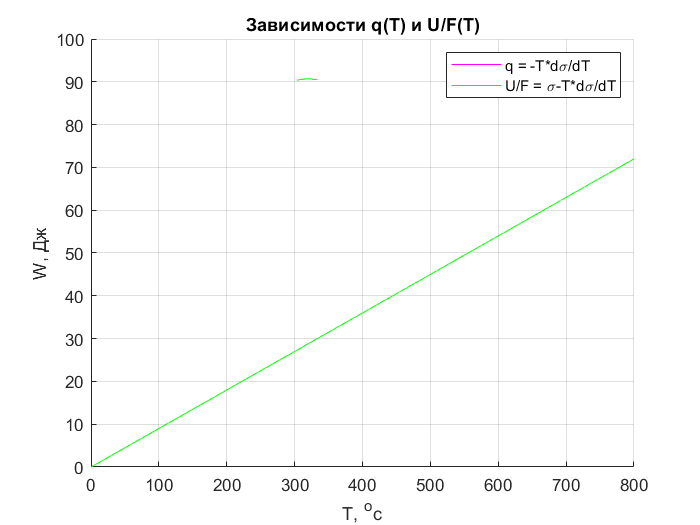

y2 = 0;
for k=0:N
    y2 = y2 + coeff1(N-k+1) * xi.^k;
end
gr1 = plot(xi, y2, 'g');

title("Зависимости q(T) и U/F(T)")
xlabel('T, ^oc')
ylabel('W, Дж')
legend("q = -T*d\sigma/dT",'U/F = \sigma-T*d\sigma/dT')
hold off